syms b_i p E_i r_i B_i
U_pure1=E_i./(1+exp(r_i.*(B_i-b_i)))-p.*b_i%用户的纯效用

$$U\_pure1 = \frac{E_{i}}{{\mathrm{e}}^{r_{i}\,\left(B_{i}-b_{i}\right)}+1}-b_{i}\,p$$

U_pure1=subs(U_pure1,[B_i,b_i,E_i],[20,25,50])

$$U\_pure1 = \frac{50}{{\mathrm{e}}^{-5\,r_{i}}+1}-25\,p$$

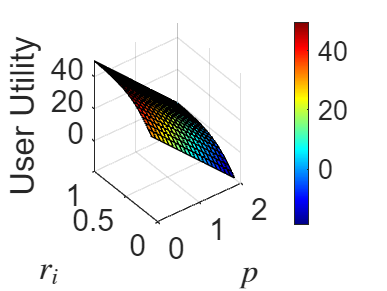

x = linspace(0,2,20);
y = linspace(0.1,1,20);
[X,Y] = meshgrid(x,y);
Z = 50./(exp((-5.*Y)) + 1) - 25.*X;
colormap jet;
surf(X,Y,Z);
colorbar;
xlabel('$p$','Interpreter','latex');
ylabel('$r_i$','Interpreter','latex')
zlabel('User Utility')
set(gca, 'FontSize', 15) %调整x轴标签字体大小为16